# Illustrate color channel spatial correlations

This analysis of the space-color correlations follows Yacov Hel-Or's 1999 paper at HP Labs.  Many people have built on this.  Hel-Or shows that the correlation between the pointwise measures is high, but the correlation between the spatial derivatives is even higher.

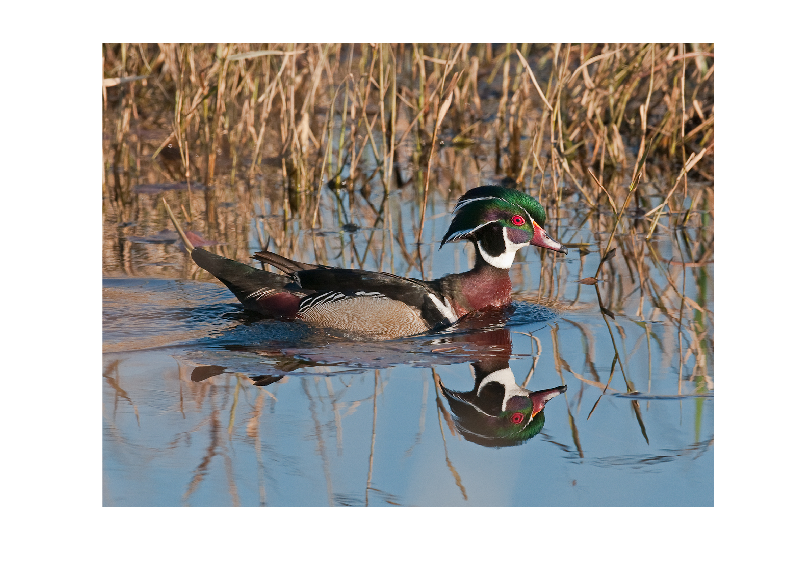

img = imread('woodDuck.png');
ieNewGraphWin; imagesc(img); axis off

## Read the color channels and plot the pointwise correlation

The scatter plots show that R/G/B are correlated, but not perfectly by any means.  

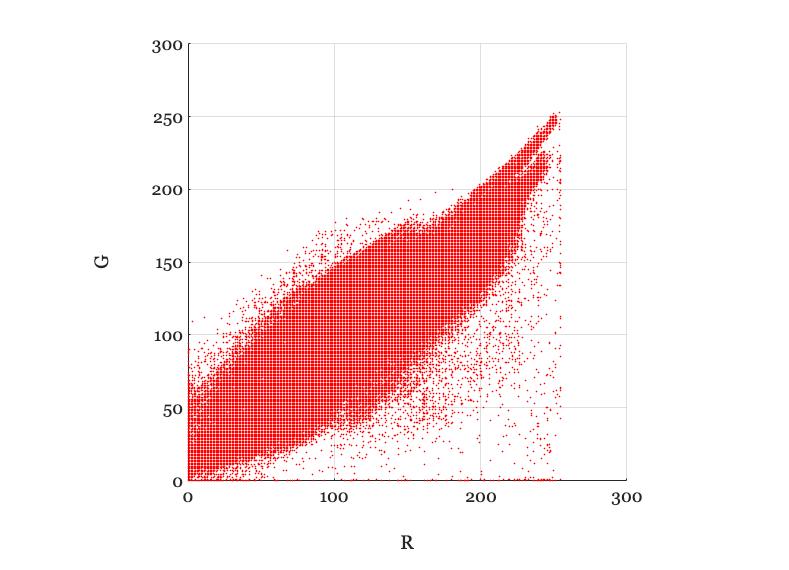

R = img(:,:,1); G = img(:,:,2); B = img(:,:,3);

sz = 1;

ieNewGraphWin;
scatter(R(:),G(:),sz); 
xlabel('R'); ylabel('G'); axis equal; axis square; grid on

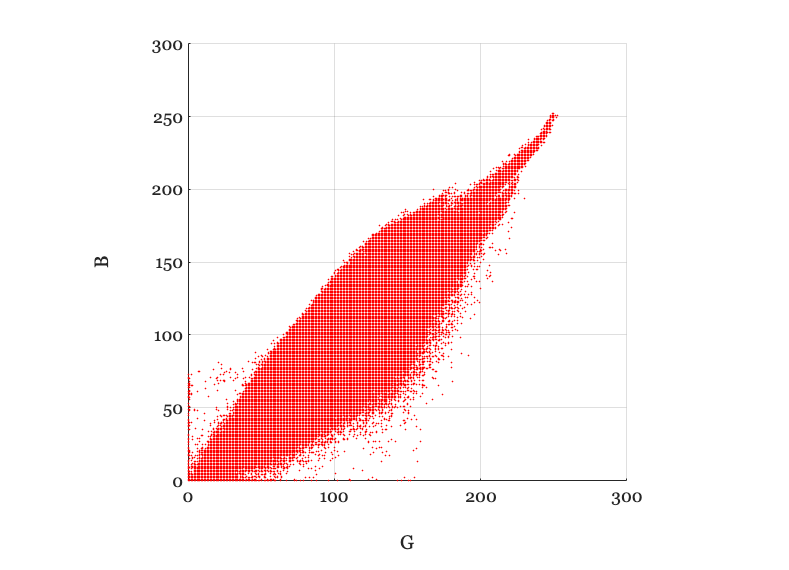


ieNewGraphWin;
scatter(G(:),B(:),1); 
xlabel('G'); ylabel('B'); axis equal; axis square; grid on

## Compute the x-derivative and plot the correlation

When we take the spatial derivative the correlations between channels increase a lot.

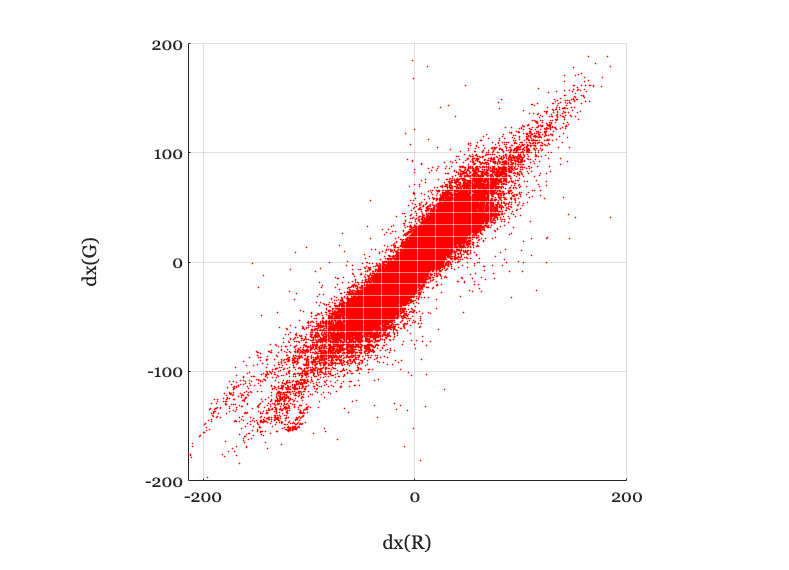

dRx = conv2(R,[1 -1],'same');
dGx = conv2(G,[1 -1],'same');
dBx = conv2(B,[1 -1],'same');

ieNewGraphWin; 
scatter(dRx(:),dGx(:),sz); 
xlabel('dx(R)'); ylabel('dx(G)');
axis equal; axis square; grid on

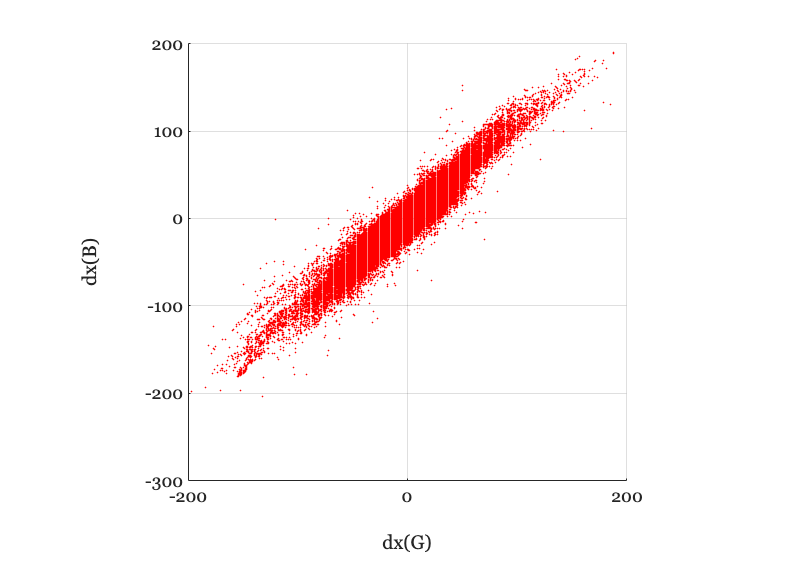


scatter(dGx(:),dBx(:),sz);
xlabel('dx(G)'); ylabel('dx(B)');
axis equal; axis square; grid on

## Process an image through a camera and repeat

s = sceneFromFile('FruitMCC_6500.tif',...
    'rgb',[],...
    displayCreate('OLED-Sony.mat'));
s = sceneSet(s,'fov',20);

camera = cameraCreate;

Camera from default oi,sensor and ip


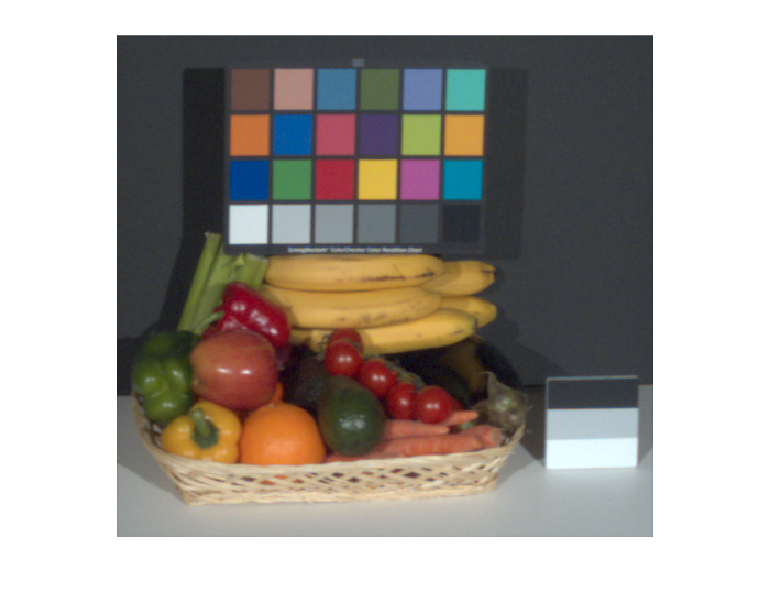

camera = cameraCompute(camera,s);
img = cameraGet(camera,'ip data srgb');
imagescRGB(img);

## The derivative images

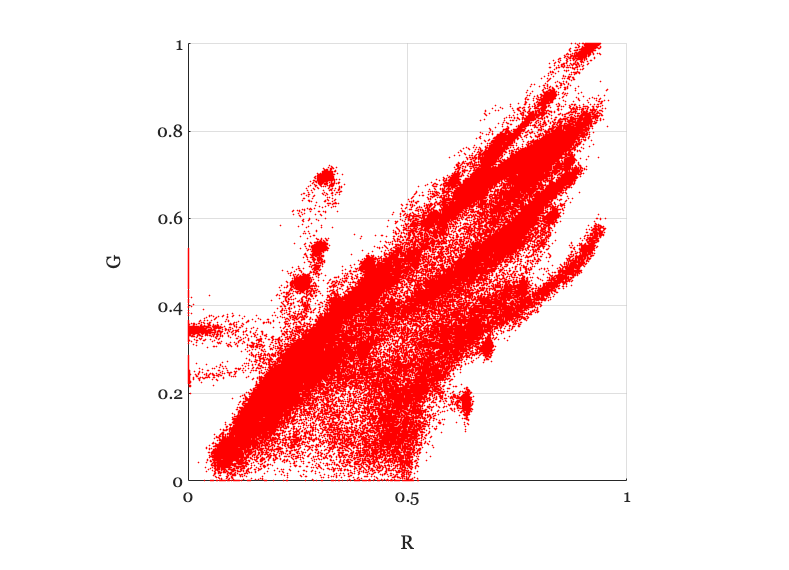

clear R
clear G
clear B
R = img(:,:,1); G = img(:,:,2); B = img(:,:,3);

sz = 1;

ieNewGraphWin;
scatter(R(:),G(:),sz); 
xlabel('R'); ylabel('G'); axis equal; axis square; grid on

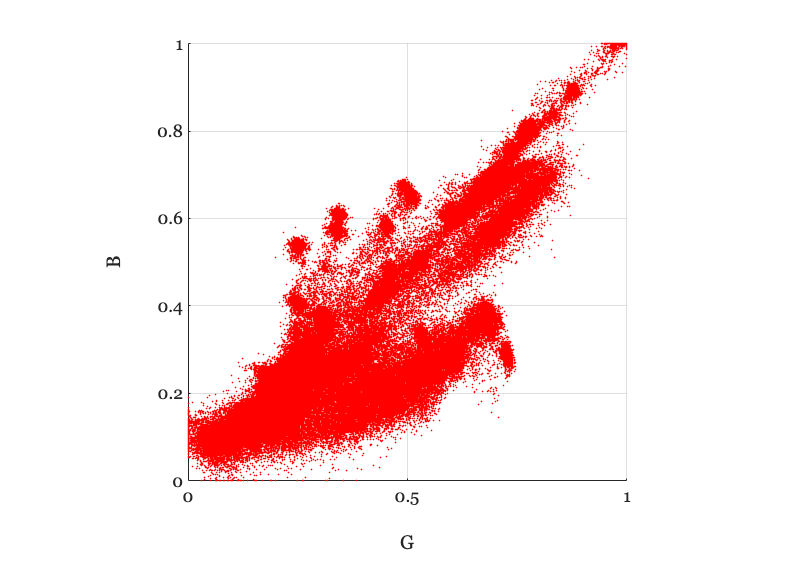


ieNewGraphWin;
scatter(G(:),B(:),1); 
xlabel('G'); ylabel('B'); axis equal; axis square; grid on

## Compute the x-derivative and plot the correlation

When we take the spatial derivative the correlations between channels increase a lot.

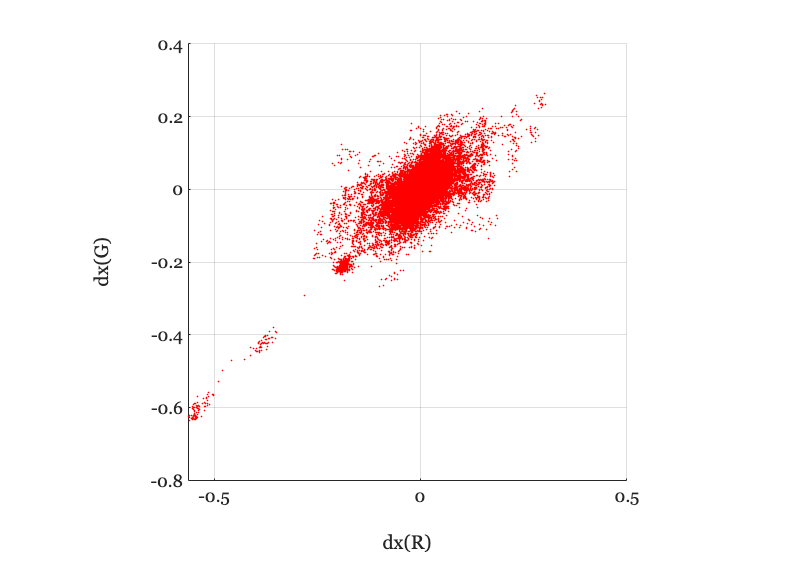

dRx = conv2(R,[1 -1],'same');
dGx = conv2(G,[1 -1],'same');
dBx = conv2(B,[1 -1],'same');

ieNewGraphWin; 
scatter(dRx(:),dGx(:),sz); 
xlabel('dx(R)'); ylabel('dx(G)');
axis equal; axis square; grid on

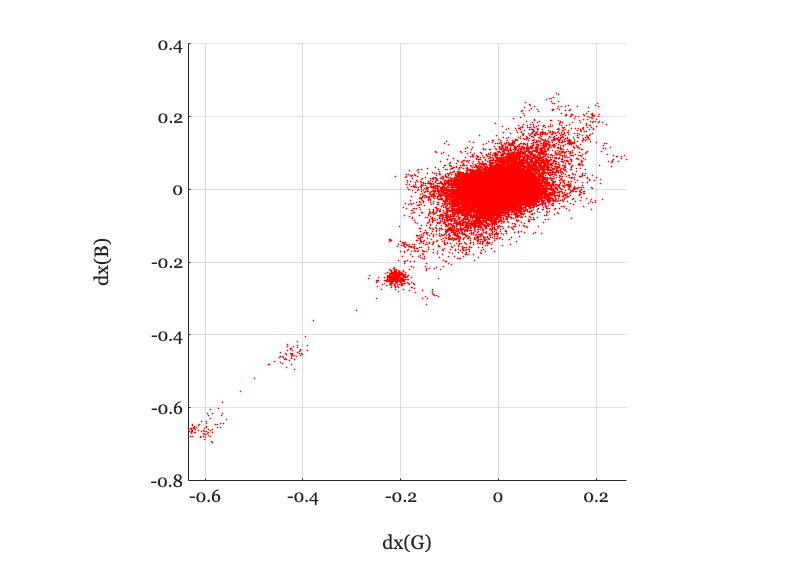


scatter(dGx(:),dBx(:),sz);
xlabel('dx(G)'); ylabel('dx(B)');
axis equal; axis square; grid on

## Luminance x- and y-derivatives

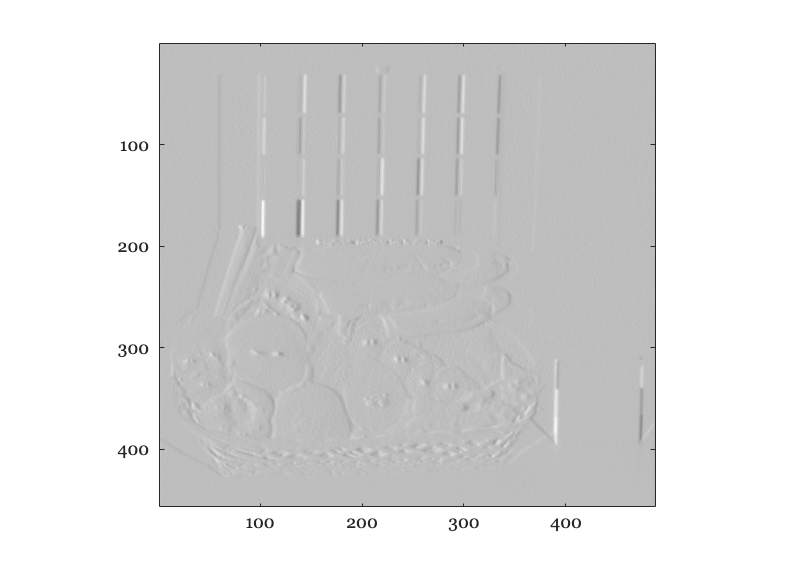

lum = sum(img,3);
dxLum = conv2(lum,[1 -1],'same');
imagesc(dxLum); axis image; colormap(gray);

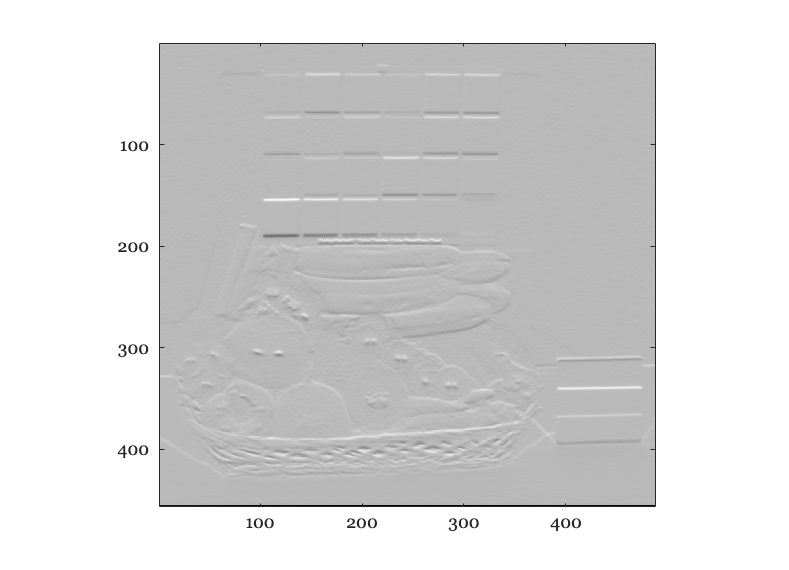


dyLum = conv2(lum,[1 -1]','same');
imagesc(dyLum); axis image; colormap(gray);